clear

gNoise = randn(100000, 1); % Gaussian noise
lNoise = randl(100000,1); % Laplacian noise
music = audioread('nuit04.wav');

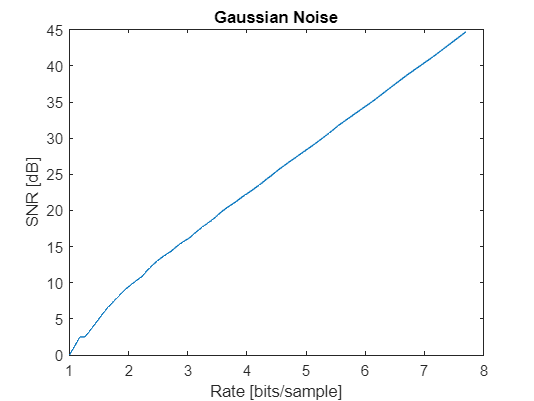

% Gaussian
gSteps = 0.02:0.01:8;
gSNRVals = zeros(size(gSteps));
gRates = zeros(size(gSteps));

for i = 1:length(gSteps)
    [gSNR, gQ]  = findSNR(gNoise, gSteps(i));
    gSNRVals(i) = gSNR;
    gRates(i) = huffman(findRelFreq(gQ));

end

gSNRVals = flip(gSNRVals);
gRates = flip(gRates);

plot(gRates, gSNRVals)
title("Gaussian Noise")
xlabel("Rate [bits/sample]")
ylabel("SNR [dB]")

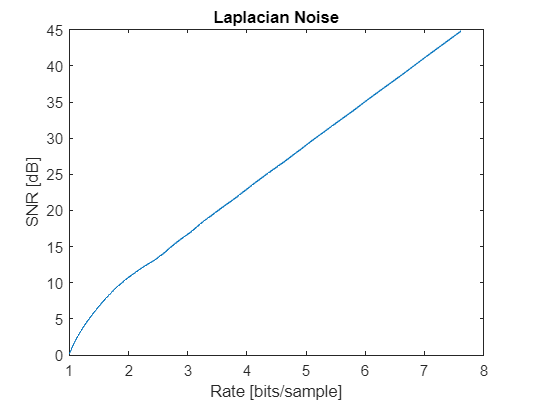

% Laplacian
lSteps = 0.02:0.01:8;
lSNRVals = zeros(size(lSteps));
lRates = zeros(size(lSteps));

for i = 1:length(lSteps)
    [lSNR, lQ]  = findSNR(lNoise, lSteps(i));
    lSNRVals(i) = lSNR;
    lRates(i) = huffman(findRelFreq(lQ));

end

lSNRVals = flip(lSNRVals);
lRates = flip(lRates);

plot(lRates, lSNRVals)

title("Laplacian Noise")
xlabel("Rate [bits/sample]")
ylabel("SNR [dB]")

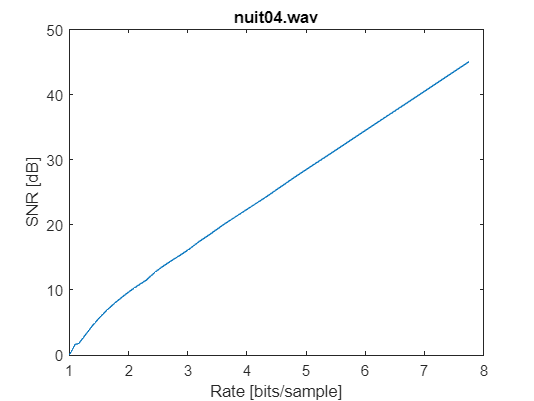

A =      0     1     1
     2     3     2
     3     0     1
     1     2     3


ans = 1.5833

% Music
mSteps = 0.003:0.01:1.5;
mSNRVals = zeros(size(mSteps));
mRates = zeros(size(mSteps));

for i = 1:length(mSteps)
    [mSNR, mQ]  = findSNR(music, mSteps(i));
    mSNRVals(i) = mSNR;
    mRates(i) = huffman(findRelFreq(mQ));

end

mSNRVals = flip(mSNRVals);
mRates = flip(mRates);

plot(mRates, mSNRVals)

title("nuit04.wav")
xlabel("Rate [bits/sample]")
ylabel("SNR [dB]")

function [SNR, q] = findSNR(x, delta)
    q = round(x/delta);
%     q(q>127) = 127;
%     q(q<-128) = -128;
    
    xhat = q*delta;
    
    D = mean((x-xhat).^2);
    sigma2 = mean(x.^2);
    SNR = 10*log10(sigma2/D);
end